%load data
mutation = readtable('mutation_sel_features_14genes.xlsx', 'ReadRowNames',true);
save('mutation.mat', 'mutation')

%load Data
load('protein.mat');
clin=xlsread('Clin_feat_for_NN.xlsx');
clin=clin';

%load('response.mat', 'T');
T= xlsread('response.xlsx');
%protein1=protein;
mutation = (table2array(mutation))';
%response= (table2array(response))';
x= {mutation; clin}

x = 2×1 cell array
    {14×198 double}
    { 6×198 double}



t = T';

% Choose a Training Function
% For a list of all training functions type: help nntrain
% 'trainlm' is usually fastest.
% 'trainbr' takes longer but may be better for challenging problems.
% 'trainscg' uses less memory. Suitable in low memory situations.
rng(1);
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.

% Create a Pattern Recognition Network
hiddenLayerSize = [6 4];
net = patternnet(hiddenLayerSize, trainFcn);
%net = patternnet(trainFcn);
%view(net)
% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 75/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 10/100;

%set crossentropy as performance eval
net.performFcn = 'crossentropy';

net.performParam.regularization = 0.1;
net.performParam.normalization = 'none';
%net = feedforwardnet(10,trainFcn);
net.numinputs = 2;
net.inputConnect= [1 1 ;0 0 ;0 0];
%6et.inputConnect = [1 1 1 1 1 1; 0 0 0 0 0 0];
% Train the Network
[net,tr] = train(net,x,t);
%view(net)
y = net(x)

y = 1×1 cell array
    {2×198 double}


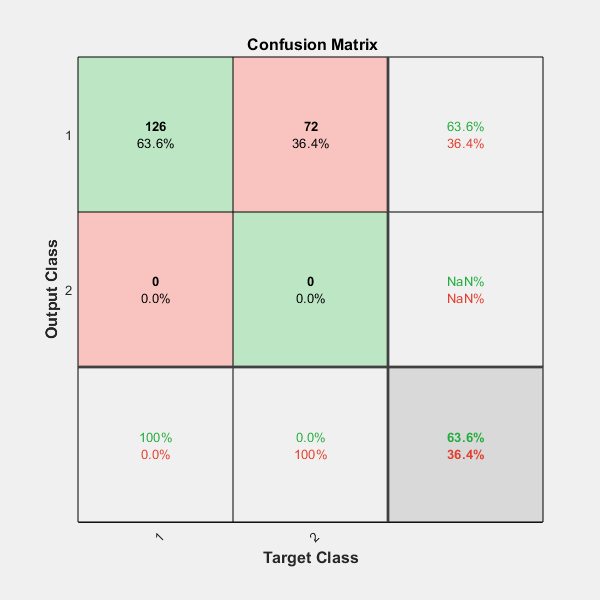


plotconfusion(t, y)

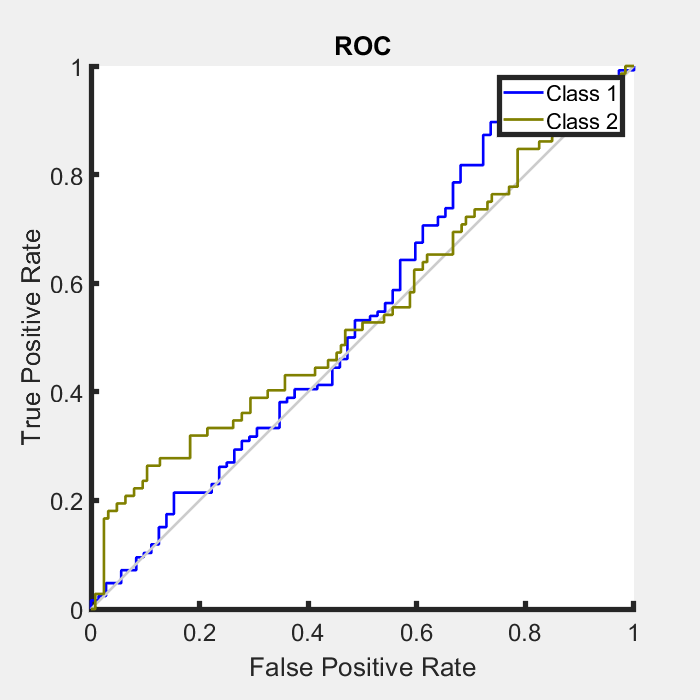

set(0,'DefaultLineLineWidth',4);
set(0,'DefaultaxesLineWidth',4);
set(0,'DefaultaxesFontSize',18);
set(0,'DefaultTextFontSize',18);
plotroc(t, y)

## VAlidation

val_mutation = readtable('mutation_out_val_final.csv','ReadRowNames',true);
save('val_mutation.mat','val_mutation')

load('val_mutation.mat')
[val_d,val_t1] = xlsread('clin_out_val_for_mutation.xlsx');
%val_resp= categorical(val_d(:,2));
%val_mirna.class=val_resp;
validation_table_mutation= val_mutation;

T_val= xlsread('Val_response_mutation.xlsx');
t_val= T_val';
val_age = val_d(:,[1])';
gender = categorical(val_t1(2:end,9));
stage=categorical(val_t1(2:end,5));
tumor=categorical(val_t1(2:end,6));
node=categorical(val_t1(2:end,7));
metastasis=categorical(val_t1(2:end,8));
t1=grp2idx(node);
t2=grp2idx(stage);
t3=grp2idx(tumor);
t4=grp2idx(gender);
t5=grp2idx(metastasis);

val_clinical_table = table(val_age',t1,t2,t3,t4,t5);
%vars = {'t1', 't2', 't3', 't4', 't5', 'gender', 'stage', 'tumor','node','metastasis','val_age'};
%clear 'vars';
val_mutationclinical=(table2array(val_clinical_table))';
%val_cnv=table2array(val_cnv);

net.numinputs = 2;
view(net)
net.inputConnect = [1 1; 0 0; 0 0];
%net.inputConnect = [0 1 0 0 0 1;0 0 0 0 0 0;0 0 0 0 0 0];
%net.inputs=3;
%X = {val_cnv.',val_cnvclinical'}
%A=zeros(166,104);
%B=zeros(61,163);
%C=zeros(107,104);
%D=zeros(19,104);
%E=zeros(14,198);
F=zeros(6,160)

F =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

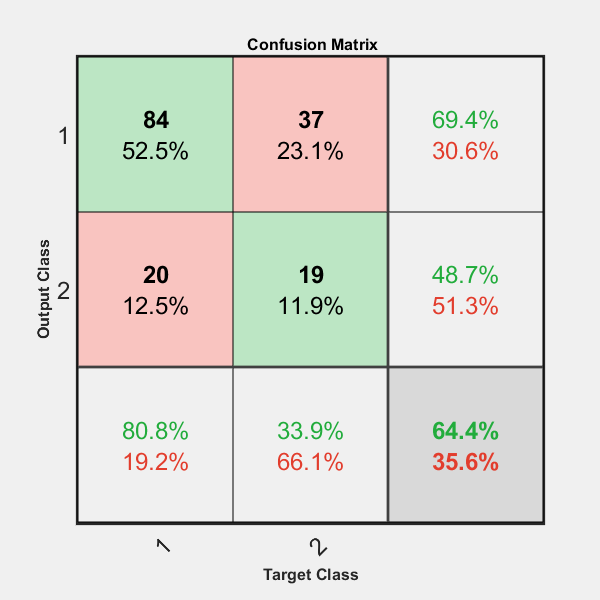


X=table2array(validation_table_mutation)';
mutationX={X; val_mutationclinical};
%mutationX={X; F};
%Y=grp2idx(val_resp)';
%y_val = sim(net, mirnaX);
y_val=net(mutationX);
view(net)
figure()
plotconfusion(t_val, y_val);

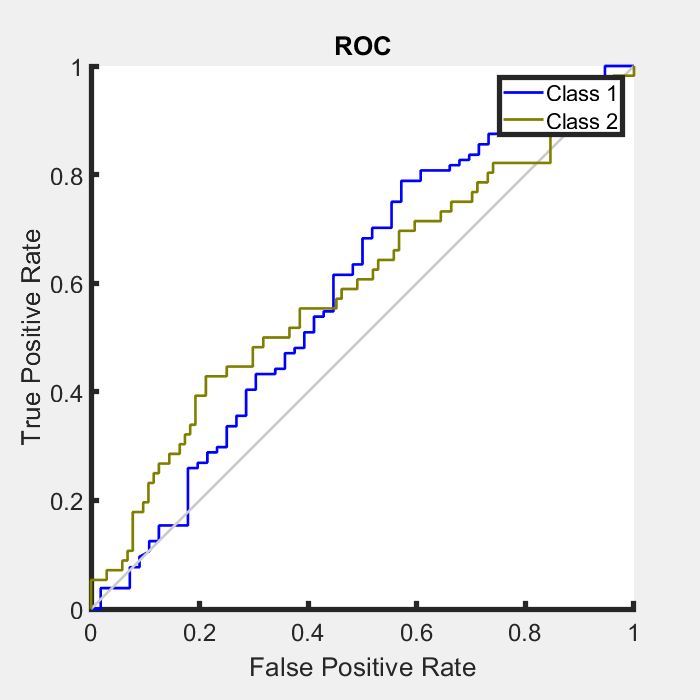

plotroc(t_val, y_val)